clear;
load('config.mat', "dirname", "block_Nx", "block_Ny");
% dirname = '.\20200421T231105\'; % 10 * 10
% dirname = '.\20200423T232037\'; % 10 * 10 noise
% dirname = '.\20200424T212550\';  % 5 * 10 noise
% dirname = '.\20200424T214617\';  % 5 * 6  noise
% block_Nx = 5;
% block_Ny = 10;
% dirname = '.\20200503T220901\';
tagPath = dirname;


## 循环读取 12 个 beacon 的数据

N_beacon = 12;
beacon_A = 0;
beacon_P = 0;

for i=1:N_beacon
    filename = sprintf('%s%s%d.mat', tagPath, 'Beacon_sig_proc_', i);
    load(filename, 'Amp_1', 'An_1', 'An_diff');
%     Amp_1 = Amp_1';
%     An_1 = An_1';
%     An_diff = An_diff';
    
    if i == 1
        beacon_A = Amp_1;
        beacon_P = An_1;
        beacon_PD = An_diff;
    else
        beacon_A = [beacon_A; Amp_1 ];
        beacon_P = [beacon_P; An_1];
        beacon_PD = [beacon_PD; An_diff];
    end
end


## 循环读取 tag 的数据, 计算距离

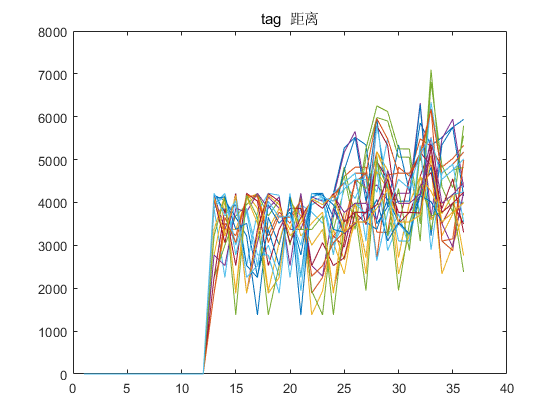

N_tag = block_Nx * block_Ny;
% tag_A = 0;
% tag_P = 0;

for i=1:N_tag
    filename = sprintf('%s%s%d.mat', tagPath, 'sig_proc_', i);
    load(filename, 'Amp_1', 'An_1', 'An_diff');
%     An_diff = An_diff';
%     tag_A = Amp_1;
%     tag_P = An_1;
%     Amp_1 = Amp_1';
%     Amp_1 = [Amp_1(1, 1:length(An_1)/3); Amp_1(1, 1+length(An_1)/3 : 2*length(An_1)/3); Amp_1(1,1+2*length(An_1)/3:end)];
%     An_1 = An_1';
%     An_1 = [An_1(1, 1:length(An_1)/3); An_1(1, 1+length(An_1)/3 : 2*length(An_1)/3); An_1(1,1+2*length(An_1)/3:end)];
%     An_diff = An_diff;
%     An_diff = [An_diff(1, 1:length(An_1)); An_diff(1, 1+length(An_1) : 2*length(An_1)); An_diff(1,1+2*length(An_1):end)];
    
    y_sig =  [beacon_A;Amp_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        distance_A = D(N_beacon + 1:end, 1:N_beacon)';
    else
        distance_A = [distance_A  D(N_beacon + 1:end, 1:N_beacon)'];
    end
    
    y_sig =  [beacon_P;An_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        distance_P = D(N_beacon + 1:end, 1:N_beacon)';
    else
        distance_P = [distance_P  D(N_beacon + 1:end, 1:N_beacon)'];
    end
    
    y_sig =  [beacon_PD;An_diff];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        distance_PD = D(N_beacon + 1:end, 1:N_beacon)';
    else
        distance_PD = [distance_PD  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

% 计算 tag 和 beacon 的距离
% y_sig =  [beacon;tag];
% D = pdist(y_sig);
% D = squareform(D);
% distance = D(N_beacon + 1:end, 1:N_beacon)';

% 12 * XXX
distance = [distance_A ;distance_P ; distance_PD];
figure;plot(distance);
title('tag  距离');

%% 保存
filename = sprintf('%s%s.mat', tagPath, 'distance');
save(filename, 'distance');

## 读取房内和房外的数据

load('.\DataSet\sample.mat', "N_inside", "N_outside");
ioPath = '.\DataSet\';

% inside
for i=1:N_inside
    filename = sprintf('%s%s%d.mat', ioPath, 'i_sig_proc_', i);
    load(filename, 'Amp_1', 'An_1', 'An_diff');
%     y_in = [Amp_1 An_1];
    
%     Amp_1 = Amp_1';
%     An_1 = An_1';
%     An_diff = An_diff';

    y_sig =  [beacon_A;Amp_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_in_A = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_in_A = [dist_in_A  D(N_beacon + 1:end, 1:N_beacon)'];
    end
        
    y_sig =  [beacon_P;An_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_in_P = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_in_P = [dist_in_P  D(N_beacon + 1:end, 1:N_beacon)'];
    end
    
    y_sig =  [beacon_PD;An_diff];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_in_PD = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_in_PD = [dist_in_PD  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

dist_in = [dist_in_A; dist_in_P;dist_in_PD];

% outside
for i=1:4*N_outside
    filename = sprintf('%s%s%d.mat', ioPath, 'o_sig_proc_', i);
    load(filename, 'Amp_1', 'An_1', 'An_diff');
%     y_out = [Amp_1 An_1];
    
%     Amp_1 = Amp_1';
%     An_1 = An_1';
%     An_diff = An_diff';

    y_sig =  [beacon_A;Amp_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_out_A = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_out_A = [dist_out_A  D(N_beacon + 1:end, 1:N_beacon)'];
    end
    
    y_sig =  [beacon_P;An_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_out_P = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_out_P = [dist_out_P  D(N_beacon + 1:end, 1:N_beacon)'];
    end
    
    y_sig =  [beacon_PD;An_diff];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_out_PD = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_out_PD = [dist_out_PD  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end
dist_out = [dist_out_A ;dist_out_P; dist_out_PD];

## 计算内外样本点和 beacon 的距离

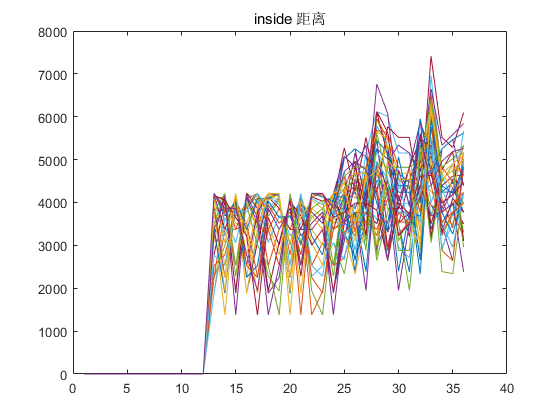

% y_io = [beacon ; y_in ; y_out];
% D_io = pdist(y_io);
% D_io = squareform(D_io);
% distance_io = D_io(N_beacon + 1:end, 1:N_beacon)';
% figure;plot(distance_io(:, 1:N_inside));
% figure;plot(distance_io(:, N_inside+1:end));
distance_io = [dist_in dist_out];
figure;plot(dist_in);
title('inside 距离');

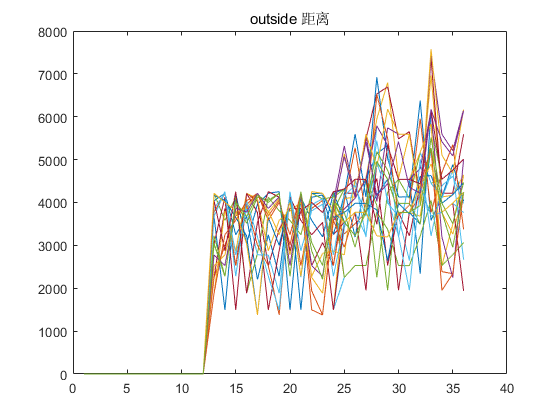

figure;plot(dist_out);
title('outside 距离');

%% 保存
ioPath = '.\DataSet\';
filename = sprintf('%s%s.mat', ioPath, 'distance_io');
save(filename, 'distance_io');

## 计算上下样本点和 beacon 的距离

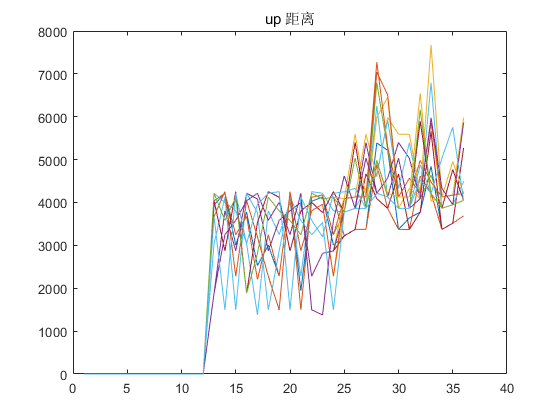

load('.\DataSet\sample.mat', "N_up", "N_dn");
udPath = '.\DataSet\';

% up
for i=1:N_up
    filename = sprintf('%s%s%d.mat', udPath, 'u_sig_proc_', i);
    load(filename, 'Amp_1', 'An_1', 'An_diff');
%     y_up = [Amp_1 An_1];
    
%     Amp_1 = Amp_1';
%     An_1 = An_1';
%     An_diff = An_diff';
    
    y_sig =  [beacon_A;Amp_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_up_A = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_up_A = [dist_up_A  D(N_beacon + 1:end, 1:N_beacon)'];
    end
    
    y_sig =  [beacon_P;An_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_up_P = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_up_P = [dist_up_P  D(N_beacon + 1:end, 1:N_beacon)'];
    end
    
    y_sig =  [beacon_PD;An_diff];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_up_PD = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_up_PD = [dist_up_PD  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

dist_up = [dist_up_A ;dist_up_P;dist_up_PD];

% down
for i=1:N_dn
    filename = sprintf('%s%s%d.mat', udPath, 'd_sig_proc_', i);
    load(filename, 'Amp_1', 'An_1', 'An_diff');
%     y_dn = [Amp_1 An_1];
    
%     Amp_1 = Amp_1';
%     An_1 = An_1';
%     An_diff = An_diff';
    
    y_sig =  [beacon_A;Amp_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_dn_A = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_dn_A = [dist_dn_A  D(N_beacon + 1:end, 1:N_beacon)'];
    end
    
    y_sig =  [beacon_P;An_1];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_dn_P = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_dn_P = [dist_dn_P  D(N_beacon + 1:end, 1:N_beacon)'];
    end
    
    y_sig =  [beacon_PD;An_diff];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_dn_PD = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_dn_PD = [dist_dn_PD  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

dist_dn = [dist_dn_A ;dist_dn_P;dist_dn_PD];


% distance_ud = [dist_up_A dist_dn_A];
figure;plot(dist_up);
title('up 距离');

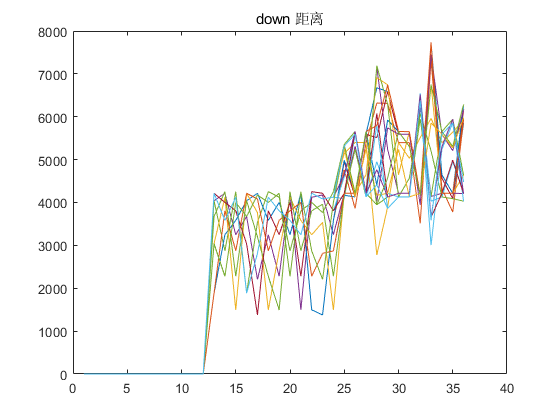

figure;plot(dist_dn);
title('down 距离');


%% 保存
filename = sprintf('%s%s.mat', udPath, 'distance_ud');
save(filename, 'dist_up', 'dist_dn');

## svm 数据集预处理

% 数据处理

%% 载入
filename = sprintf('%s%s.mat', tagPath, 'distance');
load(filename, 'distance');
N_tag = block_Nx * block_Ny;

% inside & outside
load('.\DataSet\sample.mat', "N_inside", "N_outside");
ioPath = '.\DataSet\';

filename = sprintf('%s%s.mat', ioPath, 'distance_io');
load(filename, 'distance_io');

% up & down
load('.\DataSet\sample.mat', "N_up", "N_dn");
ioPath = '.\DataSet\';

filename = sprintf('%s%s.mat', ioPath, 'distance_ud');
load(filename, 'dist_up', 'dist_dn');


dist_in = distance_io(:, 1:N_inside);
dist_out = distance_io(:,N_inside+1:end);

% 按列打乱 dist_out
rowrank = randperm(length(dist_out(1,:)));
dist_out = dist_out(:, rowrank);
rowrank = randperm(length(dist_up(1,:)));
dist_up = dist_up(:, rowrank);
rowrank = randperm(length(dist_dn(1,:)));
dist_dn = dist_dn(:, rowrank);

% 训练集  打乱
N_o_train = 20; % 40 % 20
N_u_train = 5; % 20 %15
N_d_train = 5; % 20 %15


dist_train = [distance dist_out(:, 1:N_o_train) ...
            dist_up(:, 1:N_u_train) dist_dn(:, 1:N_d_train)];
label_train = [ones(1,numel(distance(1,:))) zeros(1, N_o_train + N_u_train + N_d_train)];
% 按列打乱 dist_train label_train
rowrank = randperm(length(dist_train(1,:)));
dist_train = dist_train(:, rowrank);
label_train = label_train(:, rowrank);

% 测试集 不需要打乱
N_o_test = 4*N_outside - N_o_train;
N_u_test = N_up - N_u_train;
N_d_test = N_dn - N_d_train;

dist_test = [dist_in dist_out(:, N_o_train+1:end) ...
            dist_up(:, N_u_train+1:end) dist_dn(:, N_d_train+1:end)];
label_test = [ones(1, N_inside) zeros(1, N_o_test + N_u_test + N_d_test)];


## SVM 分类

svm_x = dist_train';
svm_y = label_train;
SVMModel = fitcsvm(svm_x, svm_y, 'KernelScale','auto','Standardize',true, 'OutlierFraction', 0.25);
% 100 * 1
label_pre = predict(SVMModel, dist_test');

label_sum = label_test' + label_pre;
N_wrong = sum(label_sum(:)==1);
rate = 1- N_wrong / length(label_sum);
disp(rate);

    0.7455




wrong = find(label_sum == 1);
disp(wrong');

  列 1 至 26

     2     4     5    16    21    36    55    56    61    62    63    66    68    69    71    72    75    76    77    80    81    83    84    87    88    90

  列 27 至 28

    93    95



pre_wrong = [label_test(wrong) ; label_pre(wrong)']

pre_wrong =      1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


CVSVMModel = crossval(SVMModel);
[~,scorePred] = kfoldPredict(CVSVMModel);
outlierRate = mean(scorePred<0)

outlierRate =     0.8083    0.1917
